## Absolute and Relative Errors

Given the exact value $x$ and its approximation $\overline{x}$, we define the absolute error as

 
$$\varepsilon_{\mathrm{abs}} =|\overline{x} -x|,$$
 

and the relative error 


$$\varepsilon_{\mathrm{rel}} =\frac{|\overline{x} -x|}{|x|}\ldotp$$


*Exercise 1*: Using the Stirling approximation we can approximate the factorial of an integer number in the following way


$$S_n =\sqrt{2\pi n}{\left(\frac{n}{e}\right)}^n \approx n!,$$


where $e=e^1$ is the exponential. Compute the absolute and relative errors and plot them with respect to $n$. Take $n=1,\ldotp \ldotp \ldotp ,13\text{ }\ldotp$

n = 1:1:13;
e = exp(1);
Sn = sqrt(2*pi.*n) .* (n./e).^n

Sn =    1.0e+09 *

   0.000000000922137   0.000000001919004   0.000000005836210   0.000000023506175   0.000000118019168   0.000000710078185   0.000004980395832   0.000039902395453   0.000359536872842   0.003598695618741   0.039615625050577   0.475687486472775   6.187239475192706



real = factorial(n)

real =    1.0e+09 *

   0.000000001000000   0.000000002000000   0.000000006000000   0.000000024000000   0.000000120000000   0.000000720000000   0.000005040000000   0.000040320000000   0.000362880000000   0.003628800000000   0.039916800000000   0.479001600000000   6.227020800000000


Eabs = abs(Sn - real)

Eabs =    1.0e+07 *

   0.000000007786299   0.000000008099565   0.000000016379041   0.000000049382487   0.000000198083204   0.000000992181536   0.000005960416839   0.000041760454734   0.000334312715805   0.003010438125897   0.030117494942255   0.331411352722508   3.978132480729485


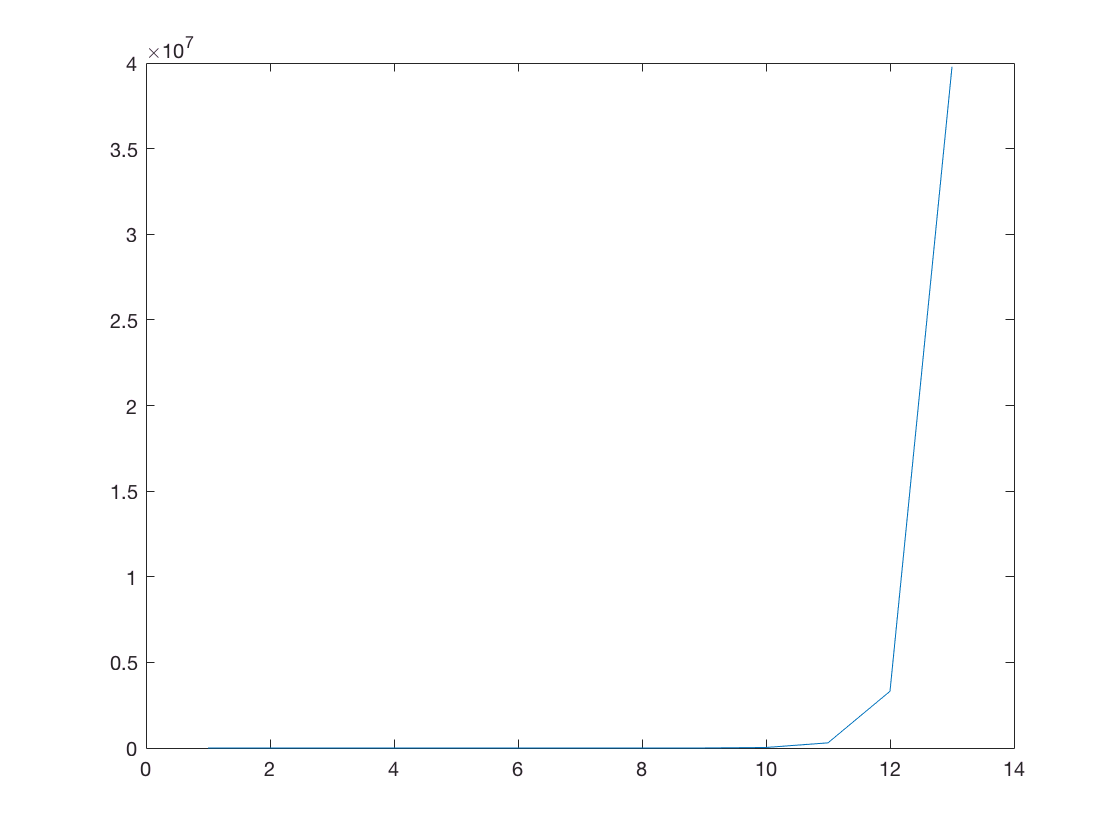

plot(n, Eabs)

*Exercise 2*: Consider the function $f\left(x\right)=e^x$. 

- Write the Maclaurin expansion of $f\left(x\right)$ for the first  $n$ terms including the expression of the error.

**Answer**: 

- Evaluate the Macluarin expansion at the points $x_1 =10$ and $x_2 =-10$ for a variable number of terms going from $n=1,\ldotp \ldotp \ldotp ,50$. Plot the relative error in terms of $n$. Evaluate the "exact" value using the `exp` function.

x1 = 10;
x2 = -10;
n = 1:1:50;
fx = exp^x
Sn = 
Erel = abs


*Exercise 3*: Consider the functions $f\left(x\right)={\left(x-1\right)}^6$ and $g\left(x\right)=x^6 -6x^5 +15x^4 -20x^3 +15x^2 -6x+1$ Plot the two functions in a neighborhood of 1 of radius $r$, with $r=0\ldotp 1,0\ldotp 01,0\ldotp 005$. Use the `subplot` command to create a 3 by 2 table of plots; plot on the left column $f\left(x\right)$ and on the right column $g\left(x\right)$; order the plots for decreasing values of $r$.  Use a `for` loop. 

% Answer




## Order of Convergence and Differentiation

The numerical process is generally an approximation of the math- ematical model obtained as a function of a discretization parameter, which we will refer to as $h$ and suppose positive. If $h\to 0$ the numerical process should return the solution of the mathematical model. If it does we say that the numerical method is *convergent*, and the error  (absolute or relative) can be bound as a function of $h$, such that


$$\varepsilon \le {\mathrm{Ch}}^p ,$$


where $C$ is a positive constant indipendent of $h$ and $p$ is a poistive number. Then we say that the method is *convergent of order* $p$. And $p$ is called *order of convergence*.	

*Example 1*: Let's use numerical differentiation as an example to undestand the order of convergence. Let's take a function $f\left(x\right)$. By definition its derivative is


$$f\text{ }'\left(x\right)=\lim_{h\to 0} \frac{f\left(x+h\right)-f\left(x\right)}{h}\ldotp$$
	

Therefore, we can approximate the derivate numerically with the *(forward) finite difference *


$$f_F '\left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}\ldotp$$


Alternatively we can define the exact derivative as 


$$f\text{ }'\left(x\right)=\lim_{h\to 0} \frac{f\left(x\right)-f\left(x-h\right)}{h},$$
	

and define the *(backward) finite difference *		


$$f_B '\left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}\ldotp$$
	

Combining the foward and backward difference we have the *centered finite difference*


$$f_C '\left(x\right)=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}\ldotp$$


*Exercise 4*: Using the forward, backward and centered finite differences, evaluate the derivative functions $f\left(x\right)=x^3$ at $x=1$. Plot the relative error as a function of $h<1$. Use `loglog` to plot the error in logarithmic scale. What is the order of convergence? Check your answer: the approximation should be exact for polynomials of order $p$, where $p$ is the order of convergence of the method; change $f\left(x\right)$ accordingly. **Answer**:

% Answer


	*Exercise 5*: Consider the 3 sequences


$$x_{n+1} =\frac{3}{4}x_n +\frac{1}{2x_n },\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }x_0 =1,$$
 


$$y_{n+1} =\frac{1}{2}y_n +\frac{1}{y_n },\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }y_0 =1,$$
 


$$z_{n+1} =\frac{3}{8}z_n +\frac{3}{2z_n }-\frac{1}{2z_n^3 },\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }z_0 =1,$$
 

converging to $\alpha =\sqrt{2}$. Plot the error  in terms of $n=1,\ldotp \ldotp \ldotp ,6$ using `semilogy`. If the sequence has the property


$$\lim_{n\to \infty } \frac{x_{n+1} -\alpha }{{\left(x_n -\alpha \right)}^p }=C,$$


for a constant $C$ then the sequence converges with order $p$. Find the order of convergence of the above sequences. In a separate figure. plot the approximate relative error as


$$\frac{|x_{n+1} -x_n |}{|x_{n+1} |},$$


for the above sequences. What is the convergence with respect to this measure of the error?

% Answer

